
$$\dot x = Ax + Bu  \\
\dot x = \left[\matrix{ A & B  }\right] \left[\matrix{ x \cr u  }\right]$$


Nombre d'états et d'entrées

nx = 2 ;
nu = 1 ;

PhasorArray Aleatoire, mreal pour être sur qu'ils sont à valeur réelle (parfois l'argument hurvizt eig (placement de pole sur A-N) produit une matrice avec une faible partie imaginaire)

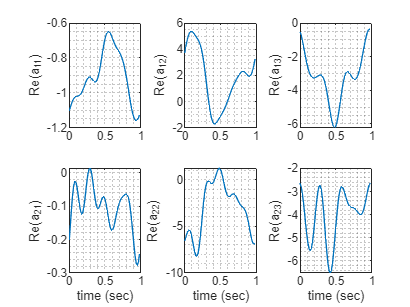

A = mreal(PhasorArray.random(nx,nx,5,"hurwitzeig",[-1 -3],"time_structure","hurwitz")) ;
B = mreal(PhasorArray.random(nx,nu,5));
figure
plot([A B])

puissance de 2 pour la largeur des creneaux en input et puissance de 2 pour l'échantillonnage de la simulation

m_u=4; %u_sampling
m_x=8; %x sampling


période du signal et nombre de période simulation

T=2*pi;
nT=1;

dtu=T/2^m_u; %dt au pas du creneaux
dtx=T/2^m_x; %dt de simulation

x0=[1 0]'; % condition initiale


Simulation de dot x = A(t) x + B(t) u, avec u constant = 1

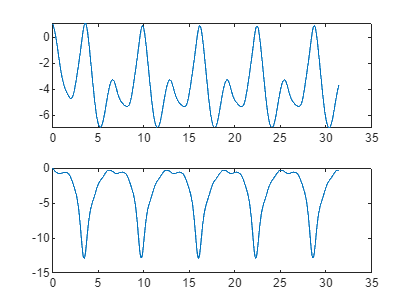

1322 successful steps
15 failed attempts
1808 function evaluations
2 partial derivatives
131 LU decompositions
1806 solutions of linear systems



figure
[out,tout]=A.lsim([0 5*T],x0,T,B*1*ones(nu,1),"isRealValued",true);

%phasorArray vides qui stockeront les valeurs
UX=PhasorArray.zeros(nu+nx,nx+nu)

UX = 3x3x1 PhasorArray of double representing a 3x3 real-valued periodic matrix with 0 harmonics

DX=PhasorArray.zeros(nx,nx+nu)

DX = 2x3x1 PhasorArray of double representing a 2x3 real-valued periodic matrix with 0 harmonics

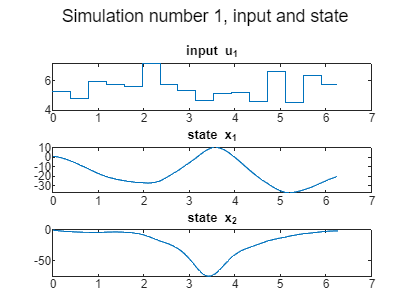

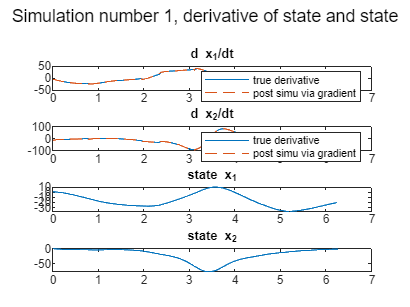

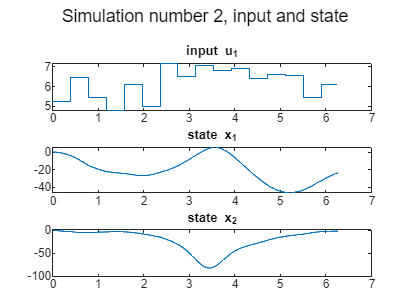

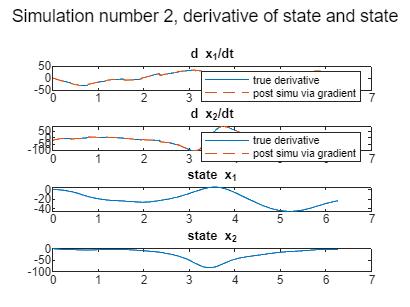

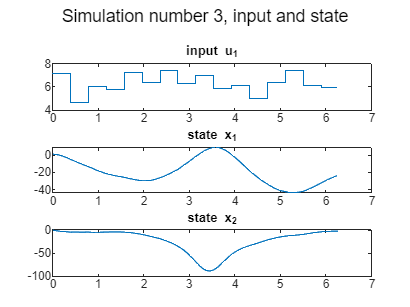

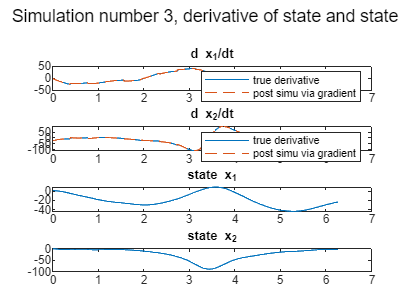


%lots de condition initiales, doit etre de longueur nu+nx
X0={[1 0]',[0 1]',[1 1]',[-1 1]'};
clear y_out dy_out u_out v_out
for x0i = 1:nx+nu
    x0=X0{x0i};
    figure
    clear u
    y=x0;
    dy=[];
    tx=[0];
    u=zeros(nu,0); %vecteur qui stockera la commande échantillonnée à période dtx
    v=zeros(nu,nT*2^m_u); %vecteur qui stockera la commande échantillonnée à période dtu
    for ii = 1:(nT*2^m_u) %pour chaque interval de longueur dtu 
        ui=3*(rand(nu,1)+1.5); %on calcule la commande créneau sur toute la longueur de l'interval
        time_simu=[tx(end):dtx:(tx(end)+dtu)]; %on sur échantillonne à période dtx
        %on simule, en imposant une sortie précisément sur le vecteur temps précédent
        %lsim output le temps de simu (ici imposé), x(t) et calcule dx(t)
        %si demandé
        [out,tout,dout]=A.lsim(time_simu,y(:,end),T,B*ui,plot=false,opts={'stats','off'},isRealValued=true); 
        
        %on concatene la sortie
        y=[y real(out(:,2:end))]; %sortie de simulation
        dy=[dy real(dout(:,1:end-1))]; %dérivée
        tx=[tx;tout(2:end)]; %temps de simu
        u=[u ui*ones(1,numel(tout)-1)]; %commande a période dtx
        v(:,ii)=ui; %commande à période dtu
    end

    %on retire l'instant final pour bien rester de longueur 2^mx
    y=y(:,1:end-1);
    tx=tx(1:end-1);

    %on transforme en phasor les signaux, en ne gardant que la premiere
    %période de simulation (cas nT>1)
    UX{1:nu,x0i}=PhasorArray.time2Phasor(permute(u(:,1:2^m_x),[1 3 2]),1,tx(1:2^m_x));
    UX{(nu+1):end,x0i}=PhasorArray.time2Phasor(permute(y(:,1:2^m_x),[1 3 2]),1,tx(1:2^m_x));
    DX{:,x0i}=PhasorArray.time2Phasor(permute(dy(:,1:2^m_x),[1 3 2]),1,tx(1:2^m_x));

    y_out(:,x0i,:)=y;
    dy_out(:,x0i,:)=dy;
    u_out(:,x0i,:)=u;
    v_out(:,x0i,:)=v;

    
    %quelques plots
    tu=0:dtu:(nT*T-dtu);
    figure
    clf
    for ii=1:nu
        subplot(nx+nu,1,ii)
        stairs(tx,u(ii,:))
        title(sprintf('input u_{%d}',ii))
    end
    for ii =1:nx
        subplot(nx+nu,1,ii+nu)
        plot(tx,y(ii,:))
        title(sprintf('state x_{%d}',ii))
    end
    sgtitle(sprintf("Simulation number %d, input and state",x0i))

    figure
    clf
    [dx,~]=gradient(y,dtx);
    for ii=1:nx
        subplot(nx+nx,1,ii)
        plot(tx,dx(ii,:))
        hold on
        plot(tx,dy(ii,:),'--')
        title(sprintf('d x_{%d}/dt',ii))
        legend('true derivative','post simu via gradient')
    end
    for ii =1:nx
        subplot(nx+nx,1,ii+nx)
        plot(tx,y(ii,:))
        title(sprintf('state x_{%d}',ii))
    end
    sgtitle(sprintf("Simulation number %d, derivative of state and state",x0i))



end

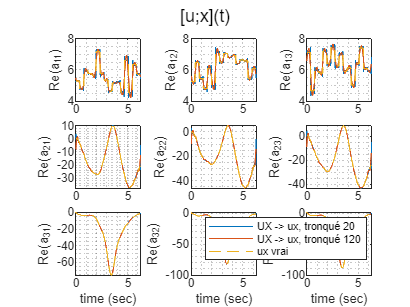


figure
clf
plot(UX.trunc(120),T)
hold on
plot(UX.trunc(20),T)
for ii =1:nu
    for jj = 1:(nx+nu)
        subplot(nx+nu,nx+nu,(ii-1)*(nx+nu)+jj)
        hold on
        plot(tx,squeeze(u_out(ii,jj,:)),'--')
    end
end
for ii =1:nx
    for jj = 1:(nx+nu)
        subplot(nx+nu,nx+nu,(ii-1)*(nx+nu)+jj+(nx+nu)*nu)
        hold on
        plot(tx,squeeze(y_out(ii,jj,:)),'--')
    end
end
sgtitle('[u;x](t)')
legend('UX -> ux, tronqué 20','UX -> ux, tronqué 120','ux vrai')

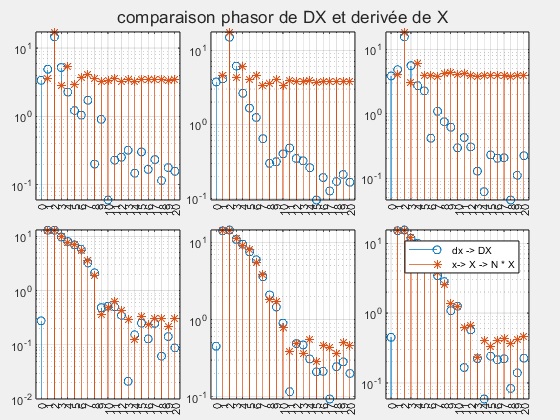

figure
clf
stem(DX.trunc(20))
hold on 
stem(d(UX{nu+1:end,:}.trunc(20),T),marker="*")
sgtitle('comparaison phasor de DX et derivée de X')
legend('dx -> DX','x-> X -> N * X')

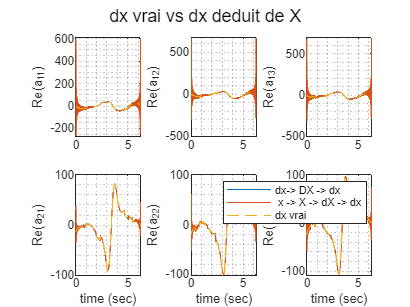


figure
plot(DX.trunc(500),T,tx)
hold on
plot(d(UX{nu+1:end,:}.trunc(500),T),T,tx)
hold on 
for ii =1:nx
    for jj = 1:(nx+nu)
        subplot(nx,nx+nu,(ii-1)*(nx+nu)+jj)
        hold on
        plot(tx,squeeze(dy_out(ii,jj,:)),'--')
    end
end

sgtitle('dx vrai vs dx deduit de X')
legend('dx-> DX -> dx',' x -> X -> dX -> dx','dx vrai')

## calcul des phasors de l'inverse.... ca marche po....

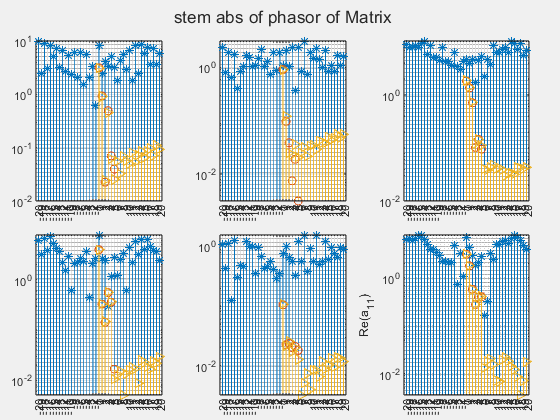

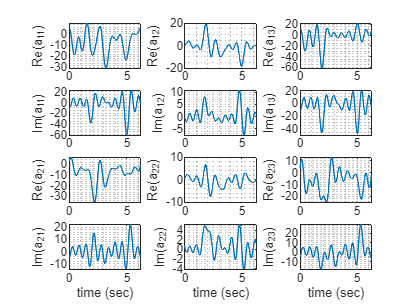

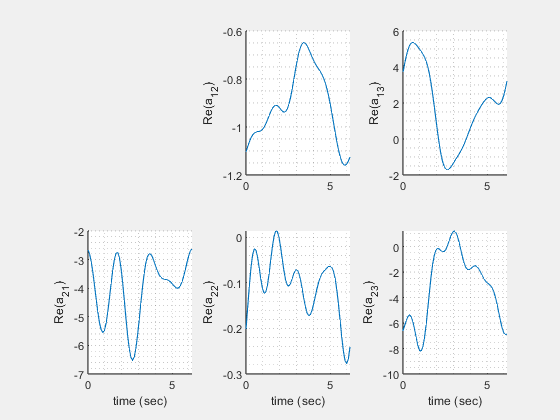

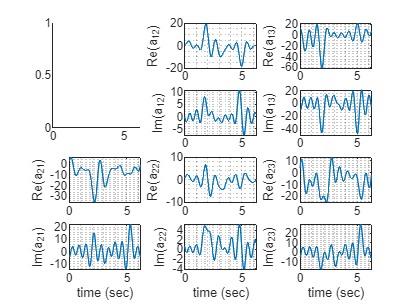

hTB=30; %nombre de truncature TB

% Inverse de la TB de UX, dont on extrait les phasor sur l'anti diag
Uinv2=PhasorArray(TB2array(UX.TB(hTB)^(-1),nu+nx));

AB=DX*Uinv2;
%inverse via l'inversion des phasors
AB1=DX*UX.inv(m=m_x+2);

figure
clf
stem(trunc(AB,20),trunc([B A],20),trunc(AB1,20),marker={'*','o','>'})

figure
plot(AB.trunc(10),T)
hold on
plot([B A],T)

Observons ce qu'il se passe

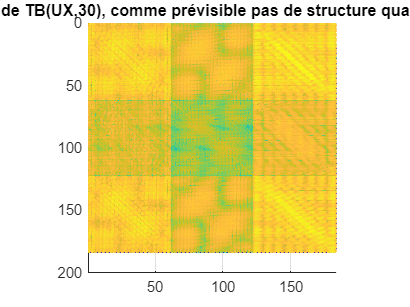

figure
barsurf(abs(UX.TB(hTB)^(-1)),'EdgeColor','interp')
view([0 90.00])
title(sprintf('Inverse de TB(UX,%d), comme prévisible pas de structure quasi toeplitz',hTB))

## Inversion sur les toeplitz block

hTB=20

hTB = 20

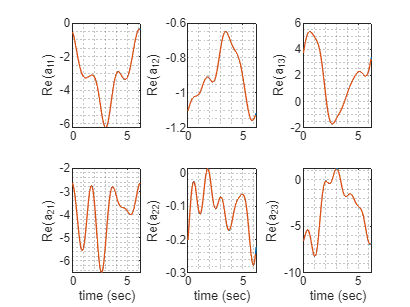

% Juste on inverse sur les toeplitz directement

BATB=DX.TB(hTB)/trunc(UX,100).TB(hTB);

BAfromTB=PhasorArray(TB2array(BATB,2));

figure
plot(BAfromTB.trunc(2^m_u),T)
hold on
plot([B A],T)

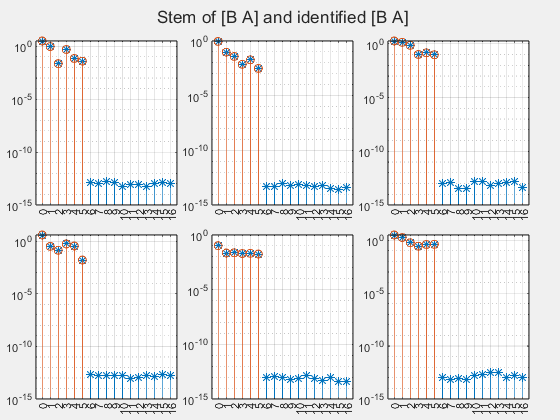


figure
clf
stem(trunc(BAfromTB,2^m_u),trunc([B A],20),marker={'*','o'})
sgtitle('Stem of [B A] and identified [B A]')

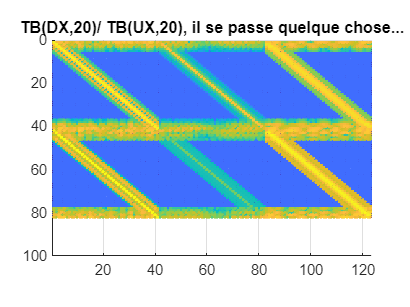

figure
barsurf(abs(BATB),'EdgeColor','interp')
view([0 90.00])
title(sprintf('TB(DX,%d)/ TB(UX,%d), il se passe quelque chose...',hTB,hTB))